# Feed Jitter

Script uses first-order linearization about the equilibrium (the origin, assuming the feed is at rest) and computes the steady-state response. First-order linearization is valid for tiny perturbations, but at the benefit of improving run-time significantly, it sacrifices a bit of precision.

Note: please do Run Section instead of Run!

**Assumptions**

- The primary reflector is relatively stiff and serves as our position reference. Only the trusses are moving from the wind.

- The jitter is therefore equivalent to the feed-subreflector-etc. sway from the primary reflector's RF axis at (0,0,z).

- The sub-reflector, feed system, etc. are consolidated into just one mass *m *at just above the focal length.

- The wind is only exerted upon this lumped element.

This is an AI-generated diagram with 3 trusses to represent the engineering model. But in this script, we can set the number of trusses.

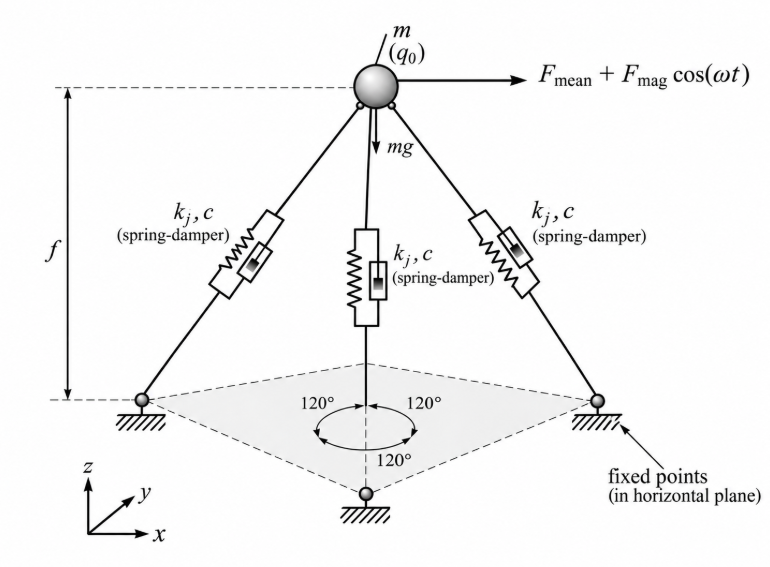

clc; clear; close all;

% initial parameters, all in SI
m = 6.5;
g = 9.81;
R = 1.0;
f = 0.91 + 0.1;
n_truss = 3;
c = 0.02; % damping constant per truss, initial estimate

% Intense Excitation force
% Modeled after a strong Boston storm-wind that is roughly periodic.

F_mean = 7;       % Constant horizontal force [N]
F_mag = 3     % Oscillating amplitude [N]

F_mag = 3

F_hz = 0.5;       % Frequency [Hz]

omega = 2*pi*F_hz;
period = 1/F_hz;


% Geometry of the trusses - hollow rods?
di_o = 0.05; % 0.05 m diameter rods
thickness = 2.0e-3;
di_i = di_o - 2*thickness;
I_rod = pi * (di_o^4 - di_i^4) / 64;
A_rod = pi * (di_o^2 - di_i^2) / 4;
E_al = 200e9;

% truss length
L = sqrt(R^2 + f^2);  % assume roughly 45 degree angle trusses

omega = 2 * pi * F_hz;
period = 1/F_hz;

k_rod = E_al * A_rod/L; % this is our benchmark [N/m]
k_vals = linspace(1e7, 1e9, 100);
fprintf('initial guess for truss diameter: %.3e [N/m]', k_rod)

initial guess for truss diameter: 4.461e+07 [N/m]

Setting up coordinates 

Coordinate frame: +z is upwards.

angles = 2 * pi * (0:n_truss-1)'/n_truss;
q0 = [0; 0; f]; % position @ equilibrium

% Angles are 0, 2*pi/n_truss, 4*pi/n_truss, ... around the z axis
angles = 2*pi*(0:n_truss-1)'/n_truss;

% One row per fixed point: [x_i, y_i, z_i]. z = 0 for every anchor
fixed_pts = [-R*cos(angles), R*sin(angles), zeros(n_truss,1)];

disp_ref = q0 - fixed_pts.'; 
L0_ref = sqrt(sum(disp_ref.^2,1));
u_ref = bsxfun(@rdivide,disp_ref,L0_ref); % unit / direction vector

% small motion damping matrix:
% C_eq = c*(u_ref * u_ref.');             % 3 x 3 matrix [N*s/m]

L0_from_k = @(kNow) L + m*g*L/(n_truss * kNow * f);
fprintf('Point-load CoG [m]: (0, 0, %.3f)\n',f);

Point-load CoG [m]: (0, 0, 0.910)


fprintf('Current truss length L = %.6f m\n',L);

Current truss length L = 1.352072 m


fprintf('Example free length L0 at k=100 N/m: %.6f m\n',L0_from_k(100));

Example free length L0 at k=100 N/m: 1.497829 m


Solve Linear Steady State for each *k *value

nOutput = 401;
M = m*eye(3);
Fmean_vec = [F_mean; 0; 0];
Famp_vec = [F_mag; 0; 0];
tOne = linspace(0,period,nOutput).';
coswt = cos(omega*tOne).';      % 1 x nOutput
sinwt = sin(omega*tOne).';      % 1 x nOutput

for j = 1:numel(k_vals)
    kj = k_vals(j);

    % Original preload convention. At q0 the spring compressions balance
    % gravity, with F_mean treated as a perturbation force.
    L0 = L + m*g*L/(n_truss*kj*f);

    K = zeros(3,3);
    C = zeros(3,3);

    % build global K and C matrices.
    for i = 1:n_truss
        ell = L0_ref(i);
        u = u_ref(:,i);
        P = u*u.';  

        K = K + kj*(P + ((ell-L0)/ell)*(eye(3)-P));
                C = C + c*P;
    end

    % solve static equilibrium
    xbar = K \ Fmean_vec;

    % build the complex dynamic stiffness matrix
    D = K - omega^2*M + 1i*omega*C;

    % solve the harmonic response
    X = D \ Famp_vec;

    % compute periodic displacement
    xOsc = real(X)*coswt - imag(X)*sinwt;

    % compute totial displacement
    x = bsxfun(@plus,xbar,xOsc);  % 3 x nOutput, relative to q0

    % compute horizontal sway
    sway = hypot(x(1,:),x(2,:));

    % COMPUTE RMS sway over one period
    % COMPUTE maximum sampled sway
    % COMPUTE mean absolute x-position
   
    sway_rms(j) = sqrt(trapz(tOne,sway.^2)/period);
    sway_max(j) = max(sway);     % sampled maximum, same as original script
    mean_x(j) = q0(1) + trapz(tOne,x(1,:))/period;

    % STORE static offset and harmonic phasor
    % MARK stiffness case as valid
    % PRINT results

    static_offset(:,j) = xbar;
    harmonic_phasor(:,j) = X;
    valid(j) = true;

    fprintf('%2d/%2d  k = %.3e N/m  RMS = %.5g um  max = %.5g um\n', ...
        j,numel(k_vals),kj,1e6*sway_rms(j),1e6*sway_max(j));
end

 1/100  k = 1.000e+07 N/m  RMS = 0.89143 um  max = 1.2187 um
 2/100  k = 2.000e+07 N/m  RMS = 0.44571 um  max = 0.60937 um
 3/100  k = 3.000e+07 N/m  RMS = 0.29714 um  max = 0.40624 um
 4/100  k = 4.000e+07 N/m  RMS = 0.22286 um  max = 0.30468 um
 5/100  k = 5.000e+07 N/m  RMS = 0.17829 um  max = 0.24375 um
 6/100  k = 6.000e+07 N/m  RMS = 0.14857 um  max = 0.20312 um
 7/100  k = 7.000e+07 N/m  RMS = 0.12735 um  max = 0.1741 um
 8/100  k = 8.000e+07 N/m  RMS = 0.11143 um  max = 0.15234 um
 9/100  k = 9.000e+07 N/m  RMS = 0.099047 um  max = 0.13541 um
10/100  k = 1.000e+08 N/m  RMS = 0.089143 um  max = 0.12187 um
11/100  k = 1.100e+08 N/m  RMS = 0.081039 um  max = 0.11079 um
12/100  k = 1.200e+08 N/m  RMS = 0.074286 um  max = 0.10156 um
13/100  k = 1.300e+08 N/m  RMS = 0.068571 um  max = 0.093749 um
14/100  k = 1.400e+08 N/m  RMS = 0.063673 um  max = 0.087052 um
15/100  k = 1.500e+08 N/m  RMS = 0.059428 um  max = 0.081249 um
16/100  k = 1.600e+08 N/m  RMS = 0.055714 um  max = 0.076171 u

Plots

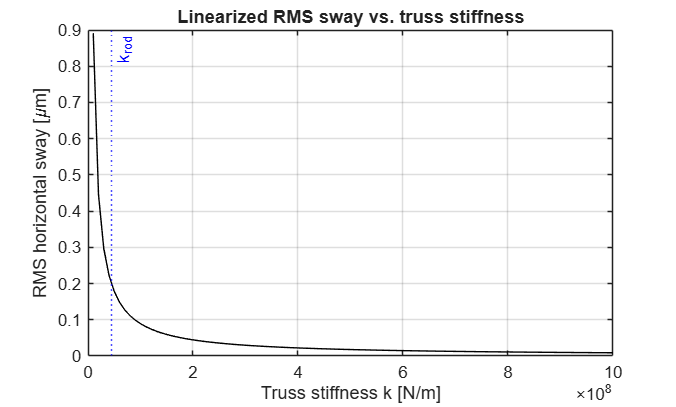

figure;
plot(k_vals,sway_rms*1e6,'k'); hold on;
xline(k_rod,'b:','k_{rod}');
xlabel('Truss stiffness k [N/m]');
ylabel('RMS horizontal sway [\mum]');
title('Linearized RMS sway vs. truss stiffness'); grid on;

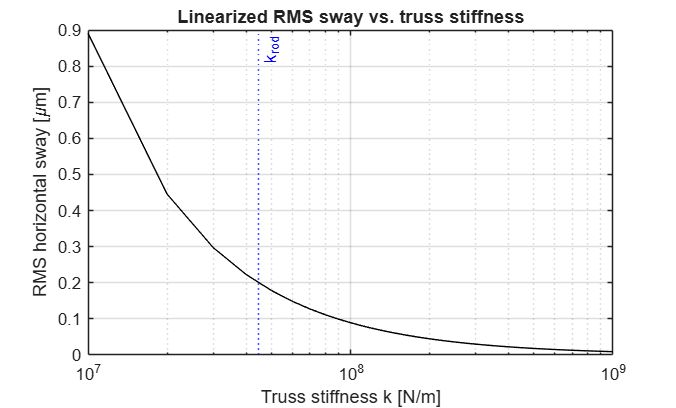


figure;
semilogx(k_vals,sway_rms*1e6,'k'); hold on;
xline(k_rod,'b:','k_{rod}');
xlabel('Truss stiffness k [N/m]');
ylabel('RMS horizontal sway [\mum]');
title('Linearized RMS sway vs. truss stiffness'); grid on;

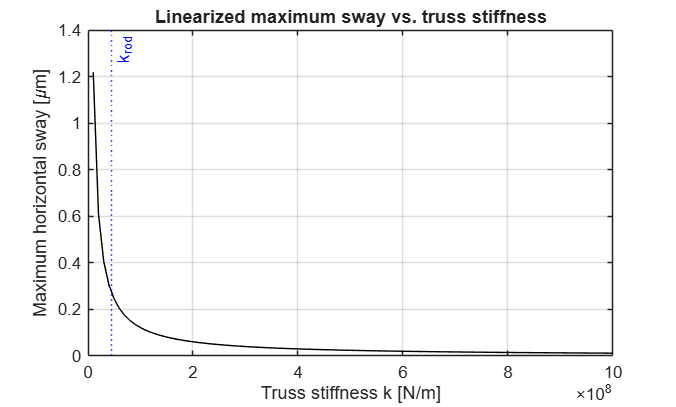


figure;
plot(k_vals,sway_max*1e6,'k'); hold on;
xline(k_rod,'b:','k_{rod}');
xlabel('Truss stiffness k [N/m]');
ylabel('Maximum horizontal sway [\mum]');
title('Linearized maximum sway vs. truss stiffness'); grid on;

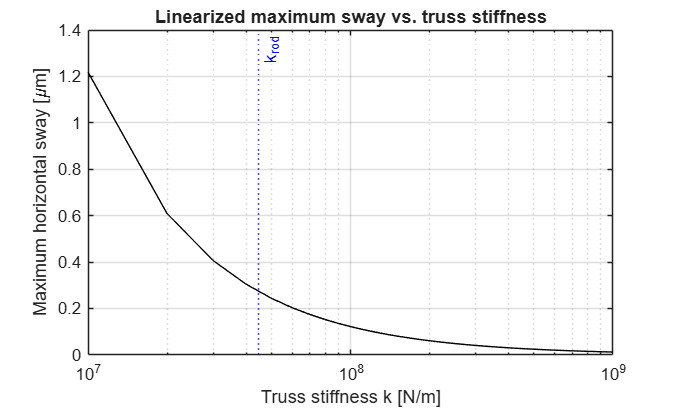


figure;
semilogx(k_vals,sway_max*1e6,'k'); hold on;
xline(k_rod,'b:','k_{rod}');
xlabel('Truss stiffness k [N/m]');
ylabel('Maximum horizontal sway [\mum]');
title('Linearized maximum sway vs. truss stiffness'); grid on;

## Deprecated! Non-linear simulation.

options = odeset('RelTol', 1e-6, 'AbsTol', 1e-8);
nOutput = 401;                     % Points over one forcing cycle


sz = size(k_vals);
sway_rms = nan(sz);
sway_max = nan(sz);
mean_x = nan(sz);
valid = false(sz);
static_offset = nan(3,numel(k_vals));
harmonic_phasor = complex(nan(3,numel(k_vals)));

Sweep for the stiffness of each truss across k values

sol = ode45(rhs, [0 10*period], z0, options);
sol.stats.nsteps     % huge -> stability-limited -> solver problem
% profile viewer     % large share of time in trussODE -> cost-per-call problem



% Number of forcing periods to simulate before recording sway
nTransientCycles = 200; % we ignore the transient period for a bit

for  j = 1:numel(k_vals)
    fprintf('Starting %d/%d: k = %.3f\n', j, numel(k_vals), k_vals(j));
    caseTimer = tic;

    % Current spring stiffness [N/m]
    kj = k_vals(j);

    % Calculate spring length at-rest.
    % This ensures that the initial position is in static equilibrium.
    % The springs must balance the gravitational force.
    L0 = L + m*g*L/(n_truss*kj*f);

    % Initial state vector:
    % z = [x; y; z; vx; vy; vz]
    % Mass starts at static equilibrium with zero velocity.
    z0 = [q0; 0; 0; 0];

    % Define the nonlinear equations of motion: z0 = rhs.
    rhs = @(t,z) trussODE(t, z, m, g, kj, c, ...
        L0, fixed_pts, F_mean, F_mag, omega);

    % Simulate initial motion to allow transients to decay.
    tTransient = nTransientCycles * period;
    [~, Ztransient] = ode15s(rhs, [0 tTransient], z0, options);

    % Use final state as initial condition for the measurement period.
    zSteady = Ztransient(end,:).';

    % Simulate one additional forcing period.
    tOne = linspace(tTransient, tTransient + period, nOutput);
    [tOne, Z] = ode45(rhs, tOne, zSteady, options);

    % Calculate horizontal sway using pythagorean
    sway = hypot(Z(:,1)-q0(1), Z(:,2)-q0(2));

    % Calculate RMS sway.
    sway_rms(j) = sqrt(trapz(tOne, sway.^2)/period);

    % Calculate maximum sway.
    sway_max(j) = max(sway);

    % Calculate mean horizontal x-position.
    mean_x(j) = trapz(tOne, Z(:,1))/period;

    % Mark simulation as completed.
    valid(j) = true;

end

Plots

% Plot RMS sway against truss stiffness
figure;
plot(k_vals, sway_rms*1e6, 'b-', 'LineWidth', 1.5);
hold on;
xline(k_rod, 'r--', 'k_{rod}', 'LineWidth', 1);
xlabel('Truss stiffness k [N/m]');
ylabel('RMS horizontal sway [um]');
title('RMS Sway vs. Truss Stiffness');
grid on;

figure;
semilogy(k_vals, sway_rms*1e6, 'b-', 'LineWidth', 1.5);
hold on;
xline(k_rod, 'r--', 'k_{rod}', 'LineWidth', 1.)
xlabel('Truss stiffness k [N/m]');
ylabel('RMS horizontal sway [um]');
title('RMS Sway vs. Truss Stiffness');
grid on;


% Plot maximum sway against truss stiffness
figure;
plot(k_vals, sway_max*1e6, 'r-', 'LineWidth', 1.5);
hold on;
xline(k_rod, 'r--', 'k_{rod}', 'LineWidth', 1);
xlabel('Truss stiffness k [N/m]');
ylabel('Maximum horizontal sway [um]');
title('Maximum Sway vs. Truss Stiffness');
grid on;


figure;
semilogy(k_vals, sway_max*1e6, 'b-', 'LineWidth', 1.5);
hold on;
xline(k_rod, 'r--', 'k_{rod}', 'LineWidth', 1.)
xlabel('Truss stiffness k [N/m]');
ylabel('RMS horizontal sway [um]');
title('RMS Sway vs. Truss Stiffness');
grid on;

**The ODE Function and what's actually happening**

in plain: $\mathrm{Acceleration}=\frac{\mathrm{Sideways\ push}+\mathrm{Gravity}+\mathrm{Spring\ forces}+\mathrm{Damping\ forces}}{\mathrm{Mass}}$

and $$\mathbf{z}=\left[\begin{array}{c}x\\y\\z\\v_x\\v_y\\v_z\end{array}\right],\qquad \dot{\mathbf{z}}=\left[\begin{array}{c}v_x\\v_y\\v_z\\a_x\\a_y\\a_z\end{array}\right]$$

In algorithmic form: $$\dot{\mathbf{z}}=\left[\begin{array}{c}\mathbf{v}\\ \frac{1}{m}\left(\left[\begin{array}{c}F_{\mathrm{mag}}\cos(\omega t)\\0\\-mg\end{array}\right]-\sum_{i=1}^{n_{\mathrm{truss}}}\left[k_j(\ell_i-L_0)+c(\mathbf{v}^{T}\mathbf{u}_i)\right]\mathbf{u}_i\right)\end{array}\right]$$

% At each instant, the algorithm:
% 1. Checks where the mass is and how fast it is moving.
% 2. Adds the sideways push and downward pull of gravity.
% 3. Checks each truss: how much it is stretched or compressed, and how fast the mass is moving along its direction.
% 4. Calculates each truss's force: the spring resists stretching or compression, while damping resists motion.
% 5. Adds all the forces and divides by the mass to find its acceleration.
% 6. Returns velocity and acceleration so the solver can calculate how the position and velocity change over time.


function dz = trussODE(t, z, m, g, kj, c, L0, fixed_pts, ...
                      F_mean, F_mag, omega)

    r = z(1:3);   % Position [m]
    v = z(4:6);   % Velocity [m/s]

    % Horizontal excitation and vertical gravity
    P = F_mean + F_mag*cos(omega*t);
    F_vec = [P; 0; -m*g];

    for i = 1:size(fixed_pts, 1)
        d = r - fixed_pts(i,:).';
        ell = norm(d);
        u = d / ell;

        extension = ell - L0;
        v_axial = dot(v, u);

        F_vec = F_vec - (kj*extension + c*v_axial)*u;
    end

    a = F_vec / m;
    dz = [v; a];
end